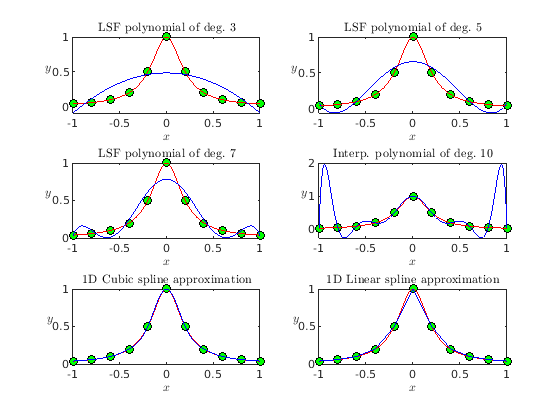

clearvars
close all

r=25.0;
f = @(x) 1./(1+r*x.^2);

x = -1:0.2:1;
y = f(x);

xx=x(1):0.01:x(end);
ff=f(xx);
n = size(x,2);

degree = [3,5,7,10];
numPlots = size(degree,2);

figure()
for k = 1:4
    p = polyfit(x,y,degree(k));
    yy = polyval(p,xx);
    subplot(3,2,k);
    plot(x,y,'o','MarkerFaceColor','green','MarkerEdgeColor','black')
    if k ~= numPlots
        title(['LSF polynomial of deg.~', num2str(degree(k))],...
            'interpreter','LaTeX','fontSize',12)
    else
        title(['Interp. polynomial of deg.~', num2str(degree(k))],...
            'interpreter','LaTeX','fontSize',12)
    end
    hold on
    xlabel('$x$','interpreter','LaTeX','fontSize',12,'rot',360)
    ylabel('$y\ $','interpreter','LaTeX','fontSize',12,'rot',360)
    plot(xx,ff,'-','color','red')
    plot(xx,yy,'-','color','blue')
    hold off
end

% Cubic splines
yy = spline(x,y,xx);
subplot(3,2,5);
plot(x,y,'o','MarkerFaceColor','green','MarkerEdgeColor','black')
title('$1$D Cubic spline approximation','interpreter','LaTeX',...
    'fontSize',12)
hold on
plot(xx,ff,'-','color','red')
plot(xx,yy,'-','color','blue')
xlabel('$x$','interpreter','LaTeX','fontSize',12,'rot',360)
ylabel('$y$','interpreter','LaTeX','fontSize',12,'rot',360)
hold off

% Linear splines
yy = interp1(x,y,xx);
subplot(3,2,6)
plot(x,y,'o','MarkerFaceColor','green','MarkerEdgeColor','black')
title('$1$D Linear spline approximation','interpreter','LaTeX',...
    'fontsize',12)
hold on
plot(xx,ff,'-','color','red')
plot(xx,yy,'-','color','blue')
xlabel('$x$','interpreter','LaTeX','fontSize',12,'rot',360)
ylabel('$y$','interpreter','LaTeX','fontSize',12,'rot',360)
hold off